Consider that the failure rate has the following form


$$\lambda(t) = c_0 + c_1 t^{n}$$



$$\lambda(t) = c_0+ c_1 t^{n}$$


We can also define an average failure rate $\lambda_{\mathrm{avg}}$:

lambda_avg = 0.343e-6 * 24*365.24/12;   % average failure rate, month^-1
T_M0 = 72;                              % typical time, months
T_T0 = 6;                               % typical time, months
n = 1.0;                                % typical exponent
plotTime = 0:0.1:144;                   % time vector for plotting (months)

We can also defined ratios of $\lambda_{\mathrm{avg}}$ for the transient and constant portions, $\beta_0$ and $\beta_1$.

Using these in combination with the definition of the average we find that 


$$\lambda {\left(t\right)}=\lambda_{avg} {\left(\beta_0 +\frac{\beta_1 {\left(n+1\right)}}{T_{M0}^n }t^n \right)}$$


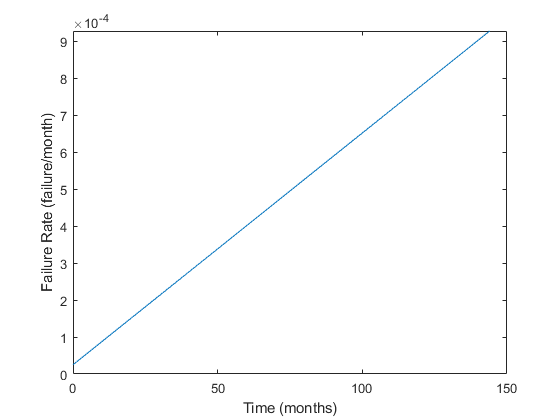

beta_0 = 0.1; % typical value for turbine valves
beta_1 = 0.9;
clf;
lambda_fun = @(t,T_T) lambda_avg*(...
    beta_0 ...
    + beta_1.*(n+1)./T_M0.^n .* t.^n);
plot(plotTime,lambda_fun(plotTime,6))
ylim([0 inf]);
xlabel('Time (months)');
ylabel('Failure Rate (failure/month)');

Recall that 


$$\lambda(t) = \frac{f(t)}{R(t)}

$$



$$\lambda(t) = \frac{f(t)}{1-F(t)}$$


So,


$$F(t) = 1-\exp\left(-\int_0^t\lambda(t)dt \right)$$


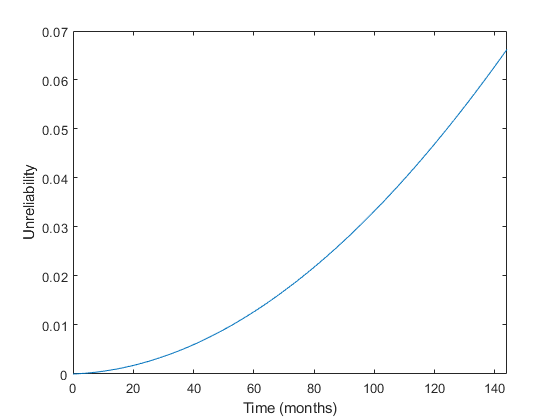

F_plain=@(t,T_T) 1-exp(-arrayfun(@(t) integral(@(tt) lambda_fun(tt,T_T),0,t),t));
clf;plot(plotTime,F_plain(plotTime,6))
xlim([0 inf])
ylabel('Unreliability')
xlabel('Time (months)')

Of course, this does not account for testing.  Testing resets everything to 0 when tested.

Therefore, it looks more like


$$F\left(t\right)=\left\lbrace \begin{array}{cc}
0 & t\le t_{0\;} \\
F^* \left(t\right)-F\left(t_0 \right) & t_0 <t\le t_{1\;} \\
F^* \left(t\right)-F\left(t_1 \right) & t_1 <t\le t_{2\;} \\
\vdots  & \vdots 
\end{array}\right.$$


or


$$F{\left(t\right)}=F^* {\left(t\right)}-F^* {\left({\left\lfloor \frac{t}{T_T }\right\rfloor }T_T \right)}$$


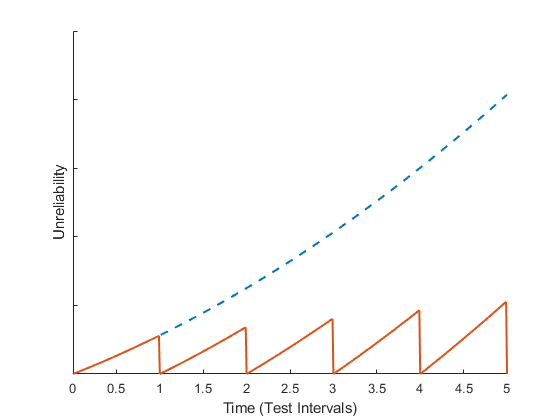

F = @(t,T_T) F_plain(t,T_T)-F_plain(floor(t./T_T).*T_T,T_T); %t is the time, T_T is the test interval
clf;hold on;
pt2= 0:0.01:5;
plot(pt2,F_plain(pt2,1),'--', 'linewidth',1.5)
plot(pt2,F(pt2,1), 'linewidth',1.5)
xlim([0 5]);
set(gca, 'yticklabel',[])
xlabel('Time (Test Intervals)')
ylabel('Unreliability')

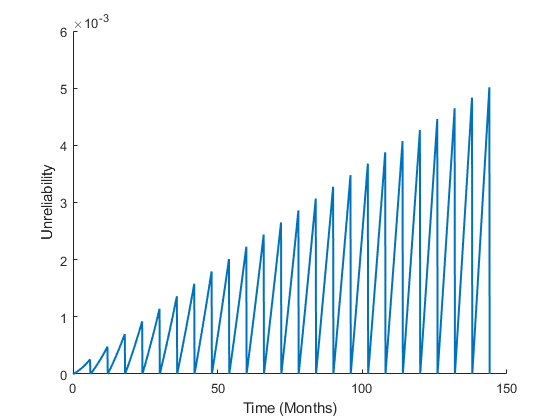

clf;hold on;
plot(plotTime,F(plotTime,6), 'linewidth',1.5)
xlabel('Time (Months)')
ylabel('Unreliability')

To make the simulation easier to run, we will take the average value across a maintenance interval.  This is also the difference in maintenance intervals, so a single average value is applied to each of the valves of interest.

Recall that the average is:


$$\bar{F} =\frac{1}{T_M }\int_0^{T_M } F\left(t\right)\textrm{dt}$$


In our case, the integral is difficult to evaluate analytically (results in a nasty Gamma function).  Therefore, we will evalaute it numerically. 

F_bar_fun = @(T_T,tLow,tHigh) 1./(tHigh-tLow) .* integral(@(t)F(t,T_T),tLow,tHigh);
F_bar_fun(3,0,72)

ans = 3.6785e-04

These values can then be used in the Monte-Carlo analysis.

We could of course build a more robust version of this function to handle all of the key inputs: $\lambda_{\mathrm{avg}}$, $\beta_{0\;}$, $\beta_1$, $T_0$ (base overhaul interval), $T$ (test interval), and $n$.  

While we do so, we will construct it using the assumption that $\beta {\;}_2 =0$.  This is conservative for changes to the test interval.  

    
$$\lambda {\left(t\right)}=\lambda_{avg} {\left(\beta_0 +\frac{\beta_1 {\left(n+1\right)}}{T_{\mathrm{M0}}^n }t^n \right)}$$



$$F{\left(t\right)}=1-\exp {\left(-\lambda_{avg} {\left(\beta_0 t+\frac{\beta_1 }{T_{M0}^n }t^{n+1} \right)}\right)}$$


% t is the time, T_T is the test interval, lambda_avg is average failure rate, 
% beta_0 is the time dependent failure ratio, beta_1 is time independent
% T_0 is the base overhaul interval, n is the time dependence exponent

lambda_fun = @(t, lambda_avg, T_T, n, T_M0, T_M, beta_0, beta_1)...
    lambda_avg*(beta_0 + beta_1.*(n+1)./T_M0.^n .* t.^n);
F_plain = @(t, lambda_avg, T_T, n,  T_M0, T_M, beta_0, beta_1)...
    1 - exp(-lambda_avg .* (beta_0.*t + beta_1./T_M0.^n .*t.^(n+1)) );
F = @(t, lambda_avg, T_T, n,  T_M0, T_M, beta_0, beta_1)...
    F_plain(t, lambda_avg, T_T, n,  T_M0, T_M, beta_0, beta_1)...
    - F_plain(floor(t./T_T).*T_T, lambda_avg, T_T, n,  T_M0, T_M, beta_0, beta_1);
F_bar_fun = @(lambda_avg, T_T, n,  T_M0, T_M, beta_0, beta_1)...
    1./(T_M-0) .* integral(@(t)F(t,lambda_avg, T_T, n,  T_M0, T_M, beta_0, beta_1),0,T_M);

We can use this to get any unreliability that we desire

%   lambda_avg      T_T     n     T_M0  T_M      beta_0  beta_1
inp=[
    2.5055E-04      3       1.00   108  108         0.309   0.691
    2.5055E-04      6       1.00   108  108         0.309   0.691
    2.5055E-04      9       1.00   108  108         0.309   0.691
    2.5055E-04      18      1.00   108  108         0.309   0.691
    2.5055E-04      3       1.00   108  126         0.309   0.691
    2.5055E-04      6       1.00   108  126         0.309   0.691
    2.5055E-04      9       1.00   108  126         0.309   0.691
    2.5055E-04      18      1.00   108  126         0.309   0.691

    ];
res=arrayfun(F_bar_fun, inp(:,1), inp(:,2), inp(:,3), inp(:,4),inp(:,5),inp(:,6),inp(:,7));
format shorte
disp(res);

   3.6825e-04
   7.3227e-04
   1.0914e-03
   2.1410e-03
   4.0951e-04
   8.1441e-04
   1.2147e-03
   2.3879e-03



format short